# Controlling the separator level

clear

## Model linarisation

% The internal states are ordered:
% P2, X2, P100 lag, L2, F200 lag, F2 lag
x_op = [50.5, 25, 194.7, 1, 208, 2];

% The inputs are orderes:
% F1, X1, T1, F2, P100, F3, F200, T200
u_op = [10, 5, 40, 2, 194.7, 50, 208, 25];

[A, B, C, D] = linmod('plant', x_op, u_op);
% Also store it in a linear system model

% Get tf enumerator and denominator coefficients from exciting F2
% (input no. 4)
[b, a] = ss2tf(A, B, C, D, 4);
% Pick out the tf coefficient in b to L2
% (output no. 4)
% Outputs are ordered:
% T3, T2, F4, L2, F5, T201, Q200, T100, Q100, F100, P2, X2
b = b(4, :);

% Create tf from the calculated coefficients
G = tf(b, a);

## Controller design

#### Trial and error 50% overshoot controller

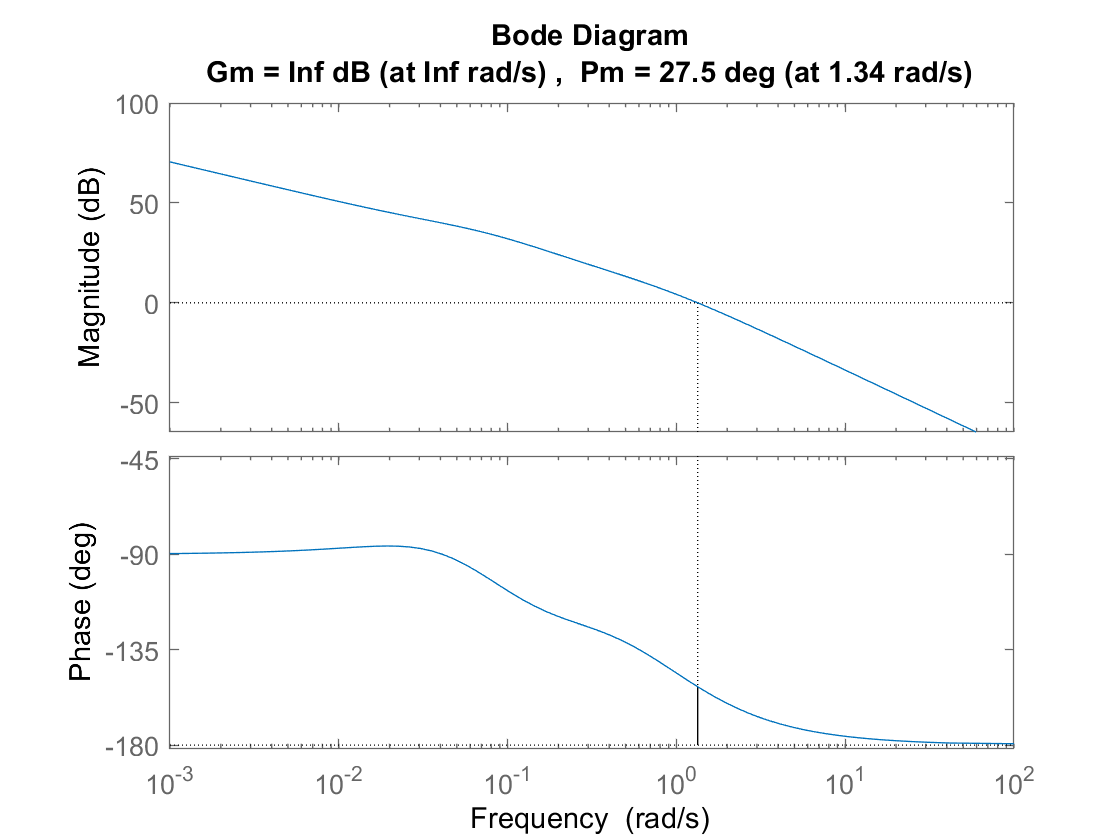

% 50% overshoot controller
margin(G * -1 * 50)

#### 45° phase margin P controller

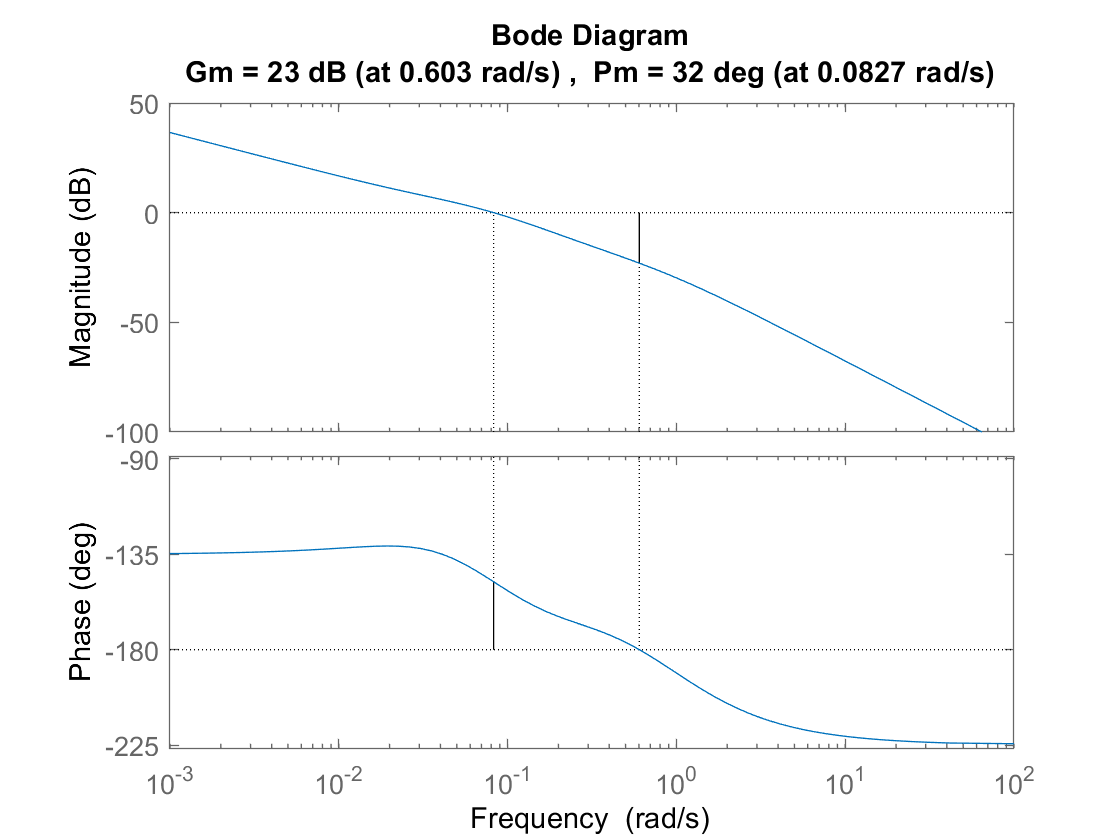

% For finding 45° phase margin gain
margin(G * -1 * exp(-pi/4 * 1i))

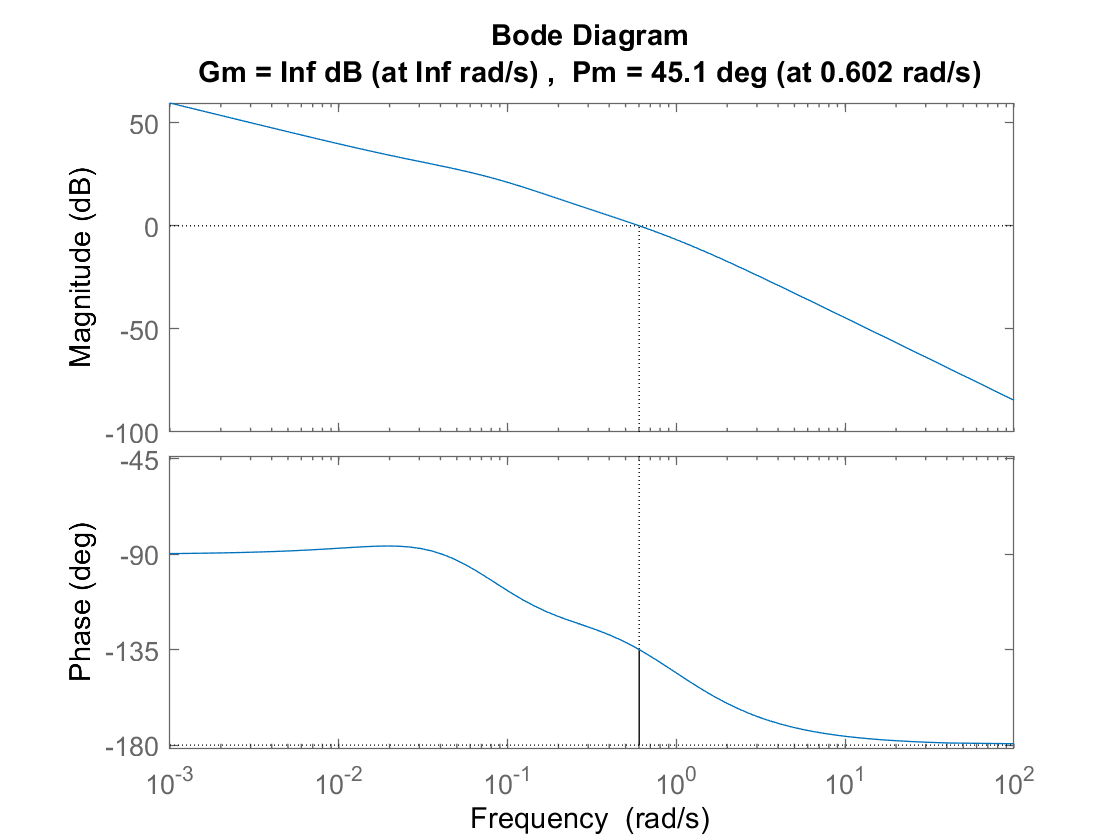

% 45° phase margin controller
margin(G * -1 * 10^(23/20))

#### 40° phase margin PI controller

% PI controller
Kp = -1 * 10^(23/20);
Ti = -1/(tan(-5 * pi/180) * 0.602);
K = tf([Kp*Ti, Kp], [Ti, 0])


tf_controller =
 
  -268.2 s - 14.13
  ----------------
      18.99 s
 
Continuous-time transfer function.



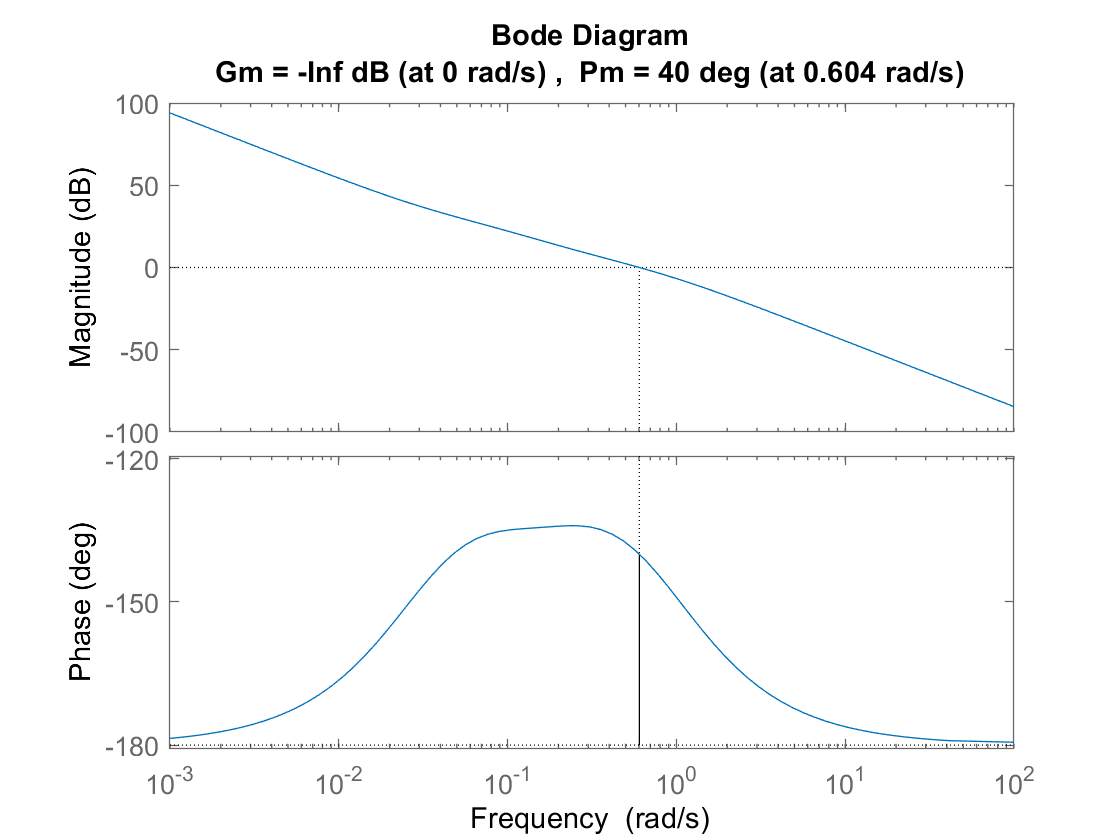


margin(G * K)

% Calculating P, I for simulink PID block
P = Kp;
I = Kp/Ti;

fprintf('The PI controller needs Ti = %0.4e', Ti)

The PI controller needs Ti = 1.8987e+01

fprintf('For implementing in the PID block P = %0.4e; I = %0.4e', P, I)

For implementing in the PID block P = -1.4125e+01; I = -7.4396e-01